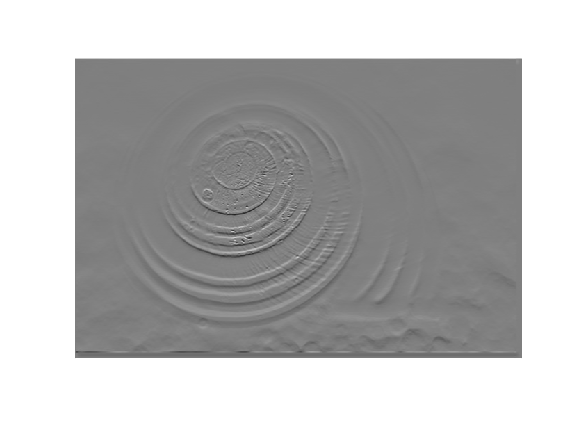


A = double(rgb2gray(imread('_61A5845.jpg')));
B = double(rgb2gray(imread('_61A5855.jpg')));
C = double(rgb2gray(imread('_61A5861.jpg')));
hy = fspecial('sobel');
hx = hy';
AY = imfilter(A,hy);
AX = imfilter(A,hx);
BY = imfilter(B,hy);
BX = imfilter(B,hx);
CY = imfilter(C,hy);
CX = imfilter(C,hx);
imshow(AY,[]);

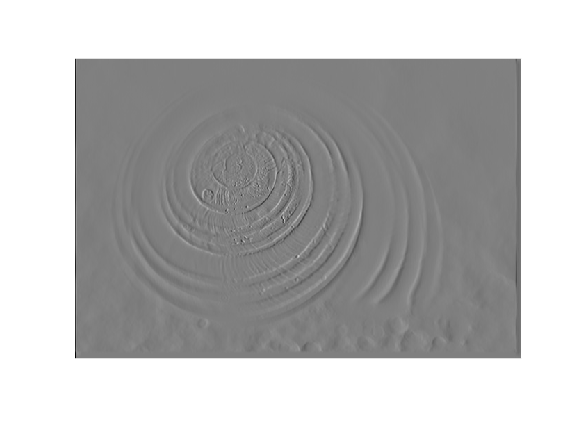

imshow(AX,[]);

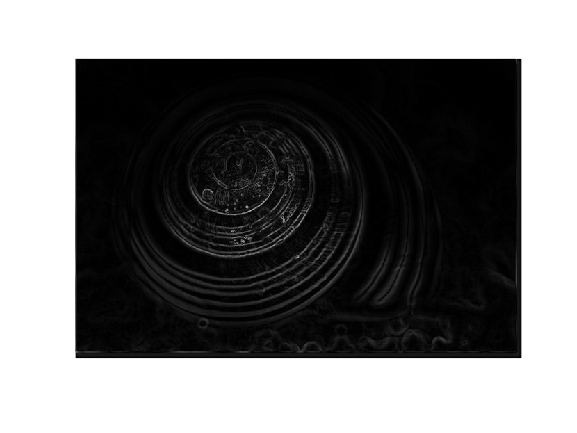

AA = abs(AY) + abs(AX);
AB = abs(BY) + abs(BX);
AC = abs(CY) + abs(CX);
imshow(AA,[]);

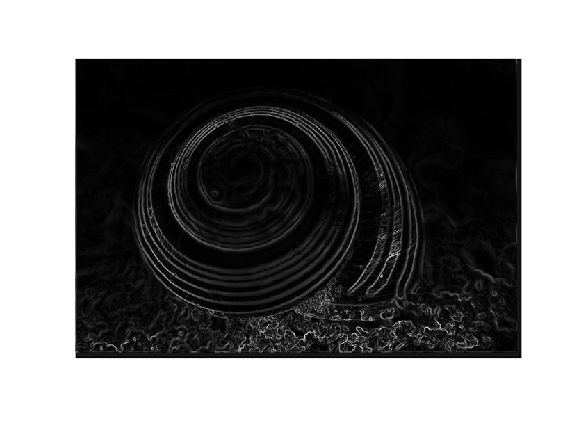

imshow(AB,[]);

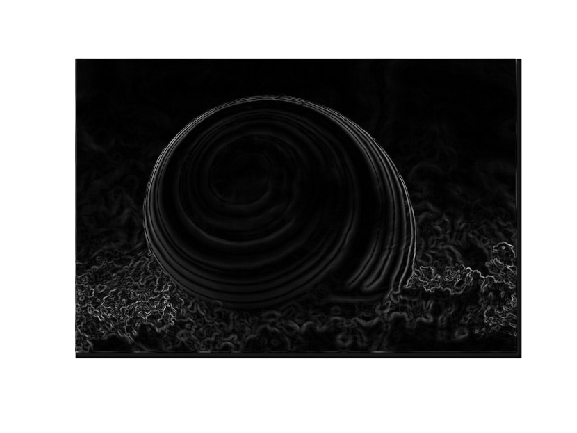

imshow(AC,[]);

Arow = size(AA,1);
Acol = size(AA,2);
Brow = size(AB,1);
Bcol = size(AB,2);
Crow = size(AC,1);
Ccol = size(AC,2);
Asigma = max([Arow Acol])/10;
Bsigma = max([Brow Bcol])/10;
Csigma = max([Crow Ccol])/10;
AG = fspecial('gaussian',[Arow Acol],Asigma);
BG = fspecial('gaussian',[Brow Bcol],Bsigma);
CG = fspecial('gaussian',[Crow Ccol],Csigma);
% Azeros = zeros(Arow, Acol);
% for i = 1:Arow
%     for j = 1:Acol
%         Azeros(i,j) = AA(i,j) * AG(i,j);
%     end
% end
% Bzeros = zeros(Brow, Bcol);
% for i = 1:Brow
%     for j = 1:Bcol
%         Bzeros(i,j) = AB(i,j) * BG(i,j);
%     end
% end
% Czeros = zeros(Crow, Ccol);
% for i = 1:Crow
%     for j = 1:Ccol
%         Czeros(i,j) = AC(i,j) * CG(i,j);
%     end
% end
% 
% Asum = sum(sum(Azeros))
% Bsum = sum(sum(Bzeros))
% Csum = sum(sum(Czeros))
AA = imfilter(AA,AG);
AB = imfilter(AB,BG);
AC = imfilter(AC,CG);
ar = 0;
for i = int16(Arow/3):int16((Arow-Arow/3))    
    for j = int16(Acol/3):int16((Acol-Acol/3))
        ar = ar + sum(sum(AA(i,j)));
    end
end
br = 0;
for i = int16(Brow/3):int16((Brow-Brow/3))    
    for j = int16(Bcol/3):int16((Bcol-Bcol/3))
        br = br + sum(sum(AB(i,j)));
    end
end

cr = 0;
for i = int16(Crow/3):int16((Crow-Crow/3))    
    for j = int16(Ccol/3):int16((Ccol-Ccol/3))
        cr = cr + sum(sum(AC(i,j)));
    end
end
ar

ar = 3.2639e+06

br

br = 3.1505e+06

cr

cr = 1.7618e+06